# `Voice Analysis and Classification Script`

`Ines Alejandro Garcia Mosqueda  A00834571`

`Paul Enrique Alonso Ramírez A01634608`

`Fernando Gabriel Gutiérrez Madrigal A01424790`

`Oliver Josel Hernández Rebollar A01641922`

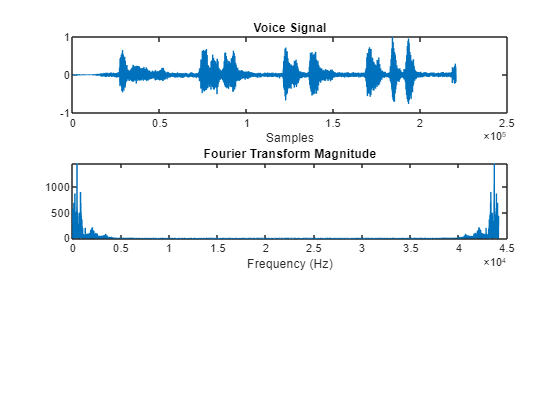

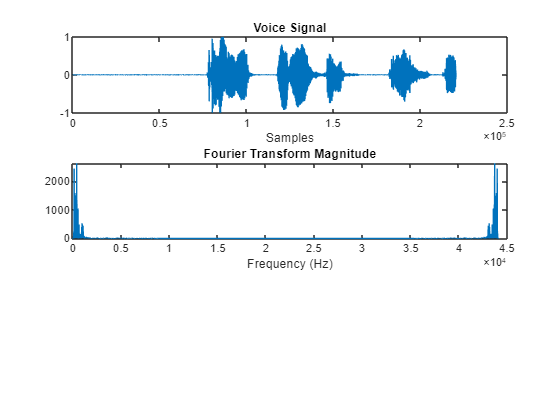

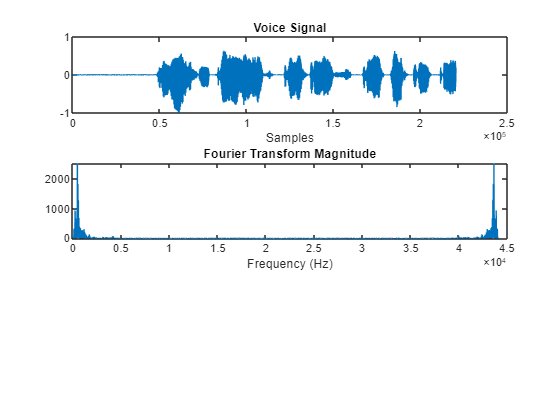

% Load the three reference signals
reference_filenames = {'C:\Users\nessy\Desktop\Analisis de voz\Fourier-Voice-Analisis\Records\my_recorded_Ines.wav', ...
                       'C:\Users\nessy\Desktop\Analisis de voz\Fourier-Voice-Analisis\Records\my_recorded_Fernando.wav', ...
                       'C:\Users\nessy\Desktop\Analisis de voz\Fourier-Voice-Analisis\Records\my_recorded_Paul.wav'};

reference_signals = cell(3, 1);
Fs = zeros(3, 1);

for i = 1:3
    [reference_signals{i}, Fs(i)] = loadAudio(reference_filenames{i});
    reference_signals{i} = preprocessAudio(reference_signals{i});
    figure;
    hold on;
    plotVoiceAndFourier(reference_signals{i},Fs(i));
    hold off;
end


% Load and preprocess the new voice signal for classification
[new_signal, Fs_new] = loadAudio('C:\Users\nessy\Desktop\Analisis de voz\Fourier-Voice-Analisis\my_recorded_voice.wav');
new_signal = preprocessAudio(new_signal);

% Classify the new signal based on the three reference signals
classification = classifyVoice(new_signal, reference_signals, Fs_new);
disp(['The new voice signal is classified as voice number ', num2str(classification)]);

The new voice signal is classified as voice number 1



% Play the testing voice signal
disp('Playing the test...');

Playing the test...


sound(new_signal,Fs_new);

% Play the similar voice signal
disp('Playing the similar...');

Playing the similar...


sound(reference_signals{classification},Fs(classification));

figure
hold on;
plotVoiceAndFourier(new_signal,Fs_new);
plotVoiceAndFourier(reference_signals{classification},Fs(classification))
hold off;

`Function to Load an Audio Signal`

function [signal, Fs] = loadAudio(filename)
    % Load a voice signal from an audio file
    [signal, Fs] = audioread(filename);
end

`Function to Preprocess the Voice Signal`

function preprocessed_signal = preprocessAudio(signal)
    % Amplitude normalization to bring it within a range of 1 to -1
    preprocessed_signal = signal / max(abs(signal));
end

`Function to Process the Voice Signal and Compute the Fourier Transform`

function [frequencies, magnitude] = processAudio(signal, Fs)
    % Calculation of the Fourier Transform
    N = length(signal); % Signal length
    frequencies = (0:N-1) * Fs / N; % Corresponding frequencies
    magnitude = abs(fft(signal)); % Magnitude of the Fourier Transform
end

Function to plot the voice signal and its Fourier Transform

function plotVoiceAndFourier(signal, Fs)
    % Process the voice signal
    [frequencies, magnitude] = processAudio(signal, Fs);
    
    % Plot the voice signal
    subplot(3, 1, 1);
    plot(signal);
    title('Voice Signal');
    xlabel('Samples');
    
    % Plot the magnitude of the Fourier Transform
    subplot(3, 1, 2);
    plot(frequencies, magnitude);
    title('Fourier Transform Magnitude');
    xlabel('Frequency (Hz)');
end

`Function to Classify a Voice Signal Based on 3 Initial Recordings`

function classification = classifyVoice(new_signal, reference_signals, Fs)
    % Process the new voice signal and the reference signals
    [frequencies_new, magnitude_new] = processAudio(new_signal, Fs);
    
    % Perform a similar processing for the reference signals
    processed_reference_signals = cell(size(reference_signals));
    for i = 1:length(reference_signals)
        [~, magnitude_reference] = processAudio(reference_signals{i}, Fs);
        % Calcula la diferencia entre las magnitudes
        diff_magnitude = abs(magnitude_new - magnitude_reference);
        % Calculate a similarity measure (lower difference implies higher similarity)
        similarity = sum(diff_magnitude);
        classification(i) = similarity;
    end
    
    % Classification will be based on the lowest difference (highest similarity)
    [~, idx] = min(classification);
    classification = idx;
end
